clc
clear

addpath("c:/git/UQ4PDE_Homeworks/Homework 3/functions/")
addpath("C:/Git/UQ4PDE_Homeworks/General functions/sobol package/")
addpath("C:/Git/UQ4PDE_Homeworks/General functions/")

% What are the optimal number of shifts and optimal number of samples for
% ML-RQMC ?

% Shifts fixed
h0 = 1/4;
LMax = 6;
M_l = 5*10^3*ones(7, 1)

M_l =         5000
        5000
        5000
        5000
        5000
        5000
        5000


%M_l = [161 86 64 48 32 4 2];
%M_l = [22 13 10 8 7 1 1]
nu = 0;
s = 1;
tic
[est, var, l_V] = Multilevel_RQMC(h0, LMax, M_l, nu, s); % Works
est

est = -1.5291

var

var = 0.0057

l_V

l_V =    14.2307
   12.7828
    0.4749
    0.2267
    0.2017
    0.0016
    0.3432


[est, var, l_V2] = Multilevel_RQMC(h0, LMax, M_l, nu, 2); % Works

toc

Elapsed time is 107.839674 seconds.




x = 0:LMax;
degree = 1;
coeff = polyfit(x, log10(l_V), degree)

coeff =    -0.4644    1.0146


var_reg = 10.^polyval(coeff, x);
coeff2 = polyfit(x, log10(l_V2), degree)

coeff2 =    -0.4843    1.0938


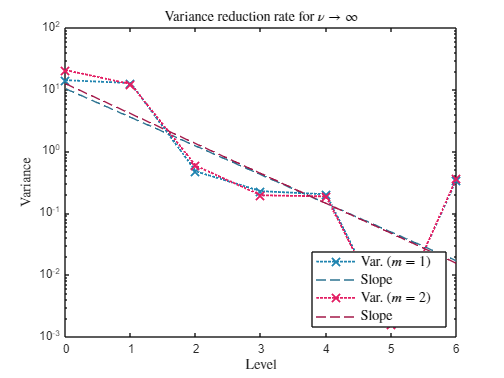

var_reg2 = 10.^polyval(coeff2, x);

figure()
ax = gca;
ax.XAxis.FontSize = 13;
ax.YAxis.FontSize = 13;
semilogy(x, l_V, 'x:', 'MarkerSize', 10, 'LineWidth', 1.5, 'color', '#2185b0')
hold on;
semilogy(x, var_reg, '--', 'color', '#2c7391')
hold on;
semilogy(x, l_V2, 'x:', 'MarkerSize', 10, 'LineWidth', 1.5, 'color', '#e31e63')
hold on;
semilogy(x, var_reg2, '--', 'color', '#a31849')
xlabel('Level', 'Interpreter', 'latex', fontsize=12)
ylabel('Variance', 'Interpreter', 'latex', fontsize=12)
title('Variance reduction rate for $\nu\to\infty$', 'Interpreter', 'latex', fontsize=12)
legend('Var. ($m=1$)', 'Slope', 'Var. ($m=2$)', 'Slope', 'Interpreter', 'latex', fontsize=12, location='southeast')

%savePDF('C:/Git/UQ4PDE_Homeworks/Homework 3/Plots/', 'CostsRateMLQMC')



%{
M = [1000, 2000, 3000, 4000];
VL0 = [11.4962, 18.5451, 15.4965, 16.0501];
VL0 = [11.4962, 7.1747, 0.5454, 1.923, 0.1505, 0.0028, 0.4696];
M = 0:length(VL0)-1;
VL1 = [7.1747, 14.5973, 9.2678, 13.8482];
VL2 = [0.5454, 0.5830, 0.6158, 0.4853];
VL3 = [0.1923, 0.1472, 0.1746, 0.2153];
VL4 = [0.1505, 0.1614, 0.2325, 0.1870];
VL5 = [0.0028, 0.0021, 0.0023, 0.0019];
VL6 = [0.4696, 0.3385, 0.4408, 0.3797];

degree = 1;
logM = log10(M);
coeff_VL0 = polyfit(logM, VL0, degree)
VL0_reg = 10 .^polyval(coeff_VL0, 0:length(VL0)-1);
logM_fit = linspace(min(logM), max(logM), 100);
y_fit = polyval(coeff_VL0, logM_fit);

semilogx(M, VL0)
hold on;
semilogx(10.^logM_fit, y_fit)
%}


%{
% Variances
V1 = [17.62 9.71 0.92 7.6222 6.5149 0.05 0.006];
V2 = [21.1005, 11.9932, 0.5001, 0.1790, 0.1867, 0.0015, 0.3741];
%Costs
V1 = [3.1571e-05, 8.4513e-05, 1.4618e-04, 2.8927e-04, 6.7645e-04, 1.3e-03, 2.5e-03];
V2 = [3.1627e-05, 8.2753e-05, 1.7021e-04, 3.1649e-04, 6.1484e-04, 1.3e-03, 2.6e-03];
%C = [3.1571e-5 8.4513e-5 1.4618e-4 2.897e-4 6.7645e-4 1.3e-3 2.5e-3];
%[msol,Msol,lambdasol] = LagrangeSolver(V, delta, TOL)
degree = 1;
coeff_V1 = polyfit(0:length(V1)-1, log10(V1), degree)
V1_reg = 10 .^polyval(coeff_V1, 0:length(V1)-1);
coeff_V2 = polyfit(0:length(V2)-1, log10(V2), degree)
V2_reg = 10 .^polyval(coeff_V2, 0:length(V2)-1);
%}

%{
figure()
ax = gca;
ax.XAxis.FontSize = 13;
ax.YAxis.FontSize = 13;
semilogy(0:length(V1)-1, V1, 'x:', 'MarkerSize', 10, 'LineWidth', 1.5, 'color', '#2185b0')
hold on;
semilogy(0:length(V1)-1, V1_reg, '--', 'color', '#2c7391')
hold on;
semilogy(0:length(V2)-1, V2, 'x:', 'MarkerSize', 10, 'LineWidth', 1.5, 'color', '#e31e63')
hold on;
semilogy(0:length(V2)-1, V2_reg, '--', 'color', '#a31849')
xlabel('Level', 'Interpreter', 'latex', fontsize=12)
ylabel('Costs in seconds', 'Interpreter', 'latex', fontsize=12)
title('Cost increase rate per level for Model 2 with paraemter $\nu$', 'Interpreter', 'latex', fontsize=12)
legend('$\nu=0.5$', 'Slope $0.3120$', '$\nu\to\infty$', 'Slope $0.3105$', 'Interpreter', 'latex', fontsize=12, location='southeast')
savePDF('C:/Git/UQ4PDE_Homeworks/Homework 3/Plots/', 'CostsRateMLQMC')
%}
%{
for i=5:6
    M = 10^(i)*ones([7 1]);
    delta = delta_find(m, M);
    i
    for j=1:length(m)
        logM = log(M);
        logdeltaM = log(delta(j, :));
        coeffM = polyfit(logM, logdeltaM, 1);
        slopeM = coeffM(1)
    end
end
%}

%LagrangeMinimizer(V, delta, TOL, C)
%[m] = lagrangian_MLQMC(V, C, delta, TOL)
%min(m)

%{
h0 = 1/4;
LMax = 6;
M_l = 10^4*ones(7, 1)
%M_l = [161 86 64 48 32 4 2];
%M_l = [22 13 10 8 7 1 1]
nu = 0;
s = 1;
tic
[est, var] = Multilevel_RQMC(h0, LMax, M_l, nu, s); % Works
est
var
toc
%}

%{
tic
[estMC, varMC] = Multilevel_MC(h0, LMax, M_l, nu);
estMC
varMC
toc
%}